clc; clear; close all;

v = [17.7309 17.1751 17.6259 16.8840 18.9354];
f = 3000:500:5000;
k = 2*pi*f./v; 
h = 0.5559/2 * ones(size(v)) / 1000;

muestras = [1 2 3 4 5];
v = v(muestras);
f = f(muestras);
k = k(muestras);
h = h(muestras);

kh = k.*h;
% Valor inicial para fsolve
eta0 = 0.85;

% Opciones de fsolve
options = optimset('Display','off');

% Usamos arrayfun para aplicar fsolve a cada par (k(i), h(i))
eta_sol = arrayfun(@(khi) ...
    fsolve(@(eta) 4*eta.*tanh(eta*khi)./tanh(khi) - (1+eta.^2).^2, ...
           eta0, options), ...
    kh);

disp('Soluciones para eta:')

Soluciones para eta:


disp(eta_sol)

    0.9482    0.9283    0.9140    0.8886    0.8902



rho = 1050;

x = eta_sol.^2

x =     0.8991    0.8617    0.8355    0.7895    0.7924


y = rho*v.^2

y = 1.0e+05 *

    3.3010    3.0973    3.2621    2.9932    3.7648


% Ajuste lineal (grado 1)
p = polyfit(x, y, 1);

% Pendiente y ordenada al origen
m = p(1);
b = p(2);

disp(['Recta ajustada: y = ' num2str(m) ' * x + ' num2str(b)])

Recta ajustada: y = -128239.3408 * x + 435530.696


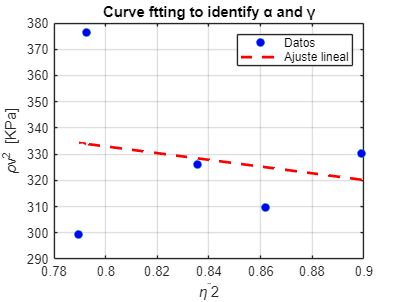


% Calcular valores ajustados
y_fit = polyval(p, x);

% Graficar
figure();
plot(x, y/1000, 'o', 'MarkerFaceColor', 'b'); hold on
plot(x, y_fit/1000, '--r', 'LineWidth', 2);
title('Curve ftting to identify α and γ')
legend('Datos', 'Ajuste lineal')
xlabel('\eta^¨2'); ylabel('\rhov^2 [KPa]');
grid on

% Resultados
alpha = b

alpha = 4.3553e+05

gamma = -m

gamma = 1.2824e+05


stress = alpha - gamma

stress = 3.0729e+05

strain = -1 + (alpha/gamma)^(1/3)

strain = 0.5031

young = stress/strain

young = 6.1075e+05